clear; clc; close all;

function [X_Est, P_Est, GT] = myEKF(out)

%% Load Calibration %%
disp('Calibration parameters generated by calibration_final.mlx, if file does not load please run.')
load('calib_params.mat');

%% Load dataset for trial in task
% Time vector
time = out.Sensor_ToF1.time;
N = length(time);

% Gyro data
gyro_raw = squeeze(permute(out.Sensor_GYRO.signals.values, [2, 3, 1])); % 1x3xM -> 3xM
gyro_time = out.Sensor_GYRO.time;

% Accelerometer data
accel_raw = squeeze(permute(out.Sensor_ACCEL.signals.values, [2, 3, 1])); % 1x3xM -> 3xM
accel_time = out.Sensor_ACCEL.time;

% ToF data
ToF1_raw = out.Sensor_ToF1.signals.values;
ToF2_raw = out.Sensor_ToF2.signals.values;
ToF3_raw = out.Sensor_ToF3.signals.values;

% Ground truth
GT_pos_raw = out.GT_position.signals.values;
GT_rot_raw = out.GT_rotation.signals.values;
GT_time = out.GT_position.time;

disp('Data setup complete.');

% EKF Parameters Setup
% Initial Ground Truth state
GT_pos0 = GT_pos_raw(1, 1:2)';
GT_q0 = GT_rot_raw(1, :);
GT_eul0 = quat2eul([GT_q0(1), GT_q0(2), GT_q0(3), GT_q0(4)], 'ZYX');
x0 = [GT_pos0; GT_eul0(1)];                     % Initial state vector x
P0 = diag([0.05^2, 0.05^2, deg2rad(2)^2]);      % Initial covariance P
Q0 = sqrt(tof_var);                             % Initial measurement noise Q

% Prediction parameters 
% [tof1_bias, tof2_bias, tof3_bias, gyro_bias_z, accel_bias_fwd, w_pos, w_yaw_rate, w_accel, initial_velocity]
% Initial velocity set to 0 m/s because cart starts from stationary
predict_params = [tof_bias(1) tof_bias(2) tof_bias(3) gyro_bias(1) accel_bias(2) 0.5 sqrt(gyro_var(1)) 0.5 0.0];
curr = stepwise(x0, P0, predict_params, Q0);

% Collect states and estimations in arrays
X_Est = zeros(3, N);        X_Est(:, 1) = curr.x;
P_Est = zeros(3, 3, N);     P_Est(:, :, 1) = curr.P;
GT = zeros(3, N);           GT(:, 1) = x0;

disp('Initial process model setup complete.');

% Run EKF predict and update
disp('EKF ESTIMATION')

for k = 1:(N-1) % Loop to predict state for step k+1
    t_k = time(k);
    t_kp1 = time(k+1);
    dt = t_kp1 - t_k;

    % --- Get Gyro Reading for Prediction Interval ---
    gyro_indices = find(gyro_time <= t_kp1);
    if isempty(gyro_indices)
        warning('myEKF:NoGyroData', 'No suitable gyro data found for interval ending at %.3f s (step %d). Assuming zero raw yaw rate.', t_kp1, k);
        gyro_z_raw = 0; % Assume zero RAW rate if no data
    else
        gyro_idx = gyro_indices(end);
        gyro_raw_vec = gyro_raw(:, gyro_idx);
        gyro_z_raw = gyro_raw_vec(1); % Get RAW gyro reading
        % Bias correction is now done INSIDE ekf.predict
    end

    % --- Get Accelerometer Reading for Prediction Interval ---
    accel_fwd_raw = 0; % Default to zero raw acceleration
    accel_indices = find(accel_time <= t_kp1);
    accel_idx = accel_indices(end);
    accel_raw_vec = accel_raw(:, accel_idx);
    accel_fwd_raw = accel_raw_vec(2); % Get RAW forward accel

    % --- EKF Predict Step ---
    predict(curr, gyro_z_raw, accel_fwd_raw, dt);


    % --- Get ToF Readings for Update Step --- (unchanged)
    current_tof_readings = [ToF1_raw(k+1); ToF2_raw(k+1); ToF3_raw(k+1)];
    update(curr, current_tof_readings);

    % --- Store Estimated State and Covariance --- (unchanged)
    X_Est(:, k+1) = curr.x;
    P_Est(:, :, k+1) = curr.P;

    % --- Get and Store Ground Truth for this time step --- (unchanged)
    [~, gt_idx] = min(abs(GT_time - t_kp1)); GT_pos = GT_pos_raw(gt_idx, 1:2)'; GT_quat = GT_rot_raw(gt_idx, :); if strcmp(lower('wxyz'), 'wxyz'); GT_eul = quat2eul([GT_quat(1), GT_quat(2), GT_quat(3), GT_quat(4)], 'ZYX'); else; GT_eul = quat2eul([GT_quat(4), GT_quat(1), GT_quat(2), GT_quat(3)], 'ZYX'); end; GT_yaw = GT_eul(1); GT(:, k+1) = [GT_pos; GT_yaw];
end
end

clear; clc; close all;

% LOAD TRIAL DATA
%file = 'trainingData/task1_5.mat';
file = 'trainingData/task2_2.mat';
data = load(file);

% FIND ESTIMATION
[X_Est, P_Est, GT_ekf] = myEKF(data.out)

Calibration parameters generated by calibration_final.mlx, if file does not load please run.
Data setup complete.


obj =   stepwise with properties:

                 x: [3×1 double]
                 P: [3×3 double]
                 R: []
     current_v_est: 0
         tof1_bias: 0.0173
         tof2_bias: []
         tof3_bias: []
       gyro_bias_z: []
    accel_bias_fwd: []
             w_pos: []
        w_yaw_rate: []
           w_accel: []
         arena_dim: []
       tof_rel_pos: []
     tof_rel_angle: []
           epsilon: []


obj =   stepwise with properties:

                 x: [3×1 double]
                 P: [3×3 double]
                 R: [3×3 double]
     current_v_est: 0.0029
         tof1_bias: 0.0173
         tof2_bias: -0.2663
         tof3_bias: -0.0173
       gyro_bias_z: 0.0019
    accel_bias_fwd: 0.0275
             w_pos: 0.5000
        w_yaw_rate: 0.0011
           w_accel: 0.5000
         arena_dim: [1×1 struct]
       tof_rel_pos: [2×3 double]
     tof_rel_angle: [1.5708 3.1416 -1.5708]
           epsilon: 1.0000e-06


obj =   stepwise with properties:

                 x: [3×1 double]
                 P: [3×3 double]
                 R: [3×3 double]
     current_v_est: 0.0029
         tof1_bias: 0.0173
         tof2_bias: -0.2663
         tof3_bias: -0.0173
       gyro_bias_z: 0.0019
    accel_bias_fwd: 0.0275
             w_pos: 0.5000
        w_yaw_rate: 0.0011
           w_accel: 0.5000
         arena_dim: [1×1 struct]
       tof_rel_pos: [2×3 double]
     tof_rel_angle: [1.5708 3.1416 -1.5708]
           epsilon: 1.0000e-06


Initial process model setup complete.
EKF ESTIMATION
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw update DISABLED.
DEBUG: ToF Yaw upda

X_Est =    -0.0171    0.0262    0.0262    0.0262    0.0274    0.0277    0.0270    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268
   -0.9464   -0.9476   -0.9477   -0.9477   -0.9477   -0.9477   -0.9466   -0.9459   -0.9453   -0.9449   -0.9446   -0.9444   -0.9442   -0.9441   -0.9440   -0.9439   -0.9439   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9437   -0.9437   -0.9437   -0.9437   -0.9437   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438 

P_Est = P_Est(:,:,1) =

    0.0025         0         0
         0    0.0025         0
         0         0    0.0012


P_Est(:,:,2) =

    0.0000    0.0000    0.0000
    0.0000    0.0001    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,3) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,4) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,5) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,6) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,7) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,8) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0012


P_Est(:,:,9) =

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.

GT_ekf =    -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171   -0.0171
   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9464   -0.9464   -0.9464   -0.9465   -0.9465   -0.9464   -0.9464   -0.9464   -0.9464   -0.9464   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465   -0.9465

% X_Est should be 3xN: [x; y; yaw]
% GT_ekf should be 3xN: [x; y; yaw] (ground truth processed by myEKF)
fprintf('Estimation complete.');

Estimation complete.

## Use compareTrajectories

Evaluate estimation by finding compareTrajectories visualization

% Ground Truth
GT_pos   = data.out.GT_position.signals.values;  % [Nx3] (X,Y,Z)
GT_rot   = data.out.GT_rotation.signals.values;  % [Nx4] (quaternion)
GT_time  = data.out.GT_position.time;            % [Nx1]

% Quaternion format extracted as wxyz considering yaw found in calibration_final.mlx
gt_quaternion_format = 'wxyz'; 

% Determine the number of estimates produced by EKF
N_est = size(X_Est, 2);

% Find corresponding indices in the raw time vector
N = N_est; % Use the length of the EKF estimates
% Truncate raw GT data to match EKF output length if needed
GT_pos = GT_pos(1:N, :);
GT_rot = GT_rot(1:N, :);
GT_time = GT_time(1:N);

gtTforms(N) = rigidtform3d; % Preprocess to rigidform3d for valid format comparison
fprintf('Creating Ground Truth rigidtform3d array...\n');

Creating Ground Truth rigidtform3d array...


for i = 1:N
    qGT_raw = quaternion(GT_rot(i,1), GT_rot(i,2), GT_rot(i,3), GT_rot(i,4));
    RGT = rotmat(qGT_raw, 'frame');

    % Extract translation (use only X, Y, Z if available, assume Z=0 if only X,Y)
    if size(GT_pos, 2) >= 3
        tGT = GT_pos(i, 1:3); % Use X, Y, Z
    else
        tGT = [GT_pos(i, 1:2), 0]; % Use X, Y, assume Z=0
    end

    gtTforms(i) = rigidtform3d(RGT, tGT); % RGT should be 3x3, tGT should be 1x3
end
fprintf('Ground Truth rigidtform3d array created.\n');

Ground Truth rigidtform3d array created.



% ------------------ Convert EKF Estimated States to rigidtform3d ------------------ %
estTforms(N) = rigidtform3d  % Preallocate

estTforms =   1×6791 rigidtform3d array with properties:

    Dimensionality
    Translation
    R
    A


X_Est

X_Est =    -0.0171    0.0262    0.0262    0.0262    0.0274    0.0277    0.0270    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268
   -0.9464   -0.9476   -0.9477   -0.9477   -0.9477   -0.9477   -0.9466   -0.9459   -0.9453   -0.9449   -0.9446   -0.9444   -0.9442   -0.9441   -0.9440   -0.9439   -0.9439   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9437   -0.9437   -0.9437   -0.9437   -0.9437   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438   -0.9438 

fprintf('Creating Estimated (EKF) rigidtform3d array...\n');

Creating Estimated (EKF) rigidtform3d array...


for i = 1:N
    % Estimated position (X, Y from EKF, assume Z=0)
    tEst = [X_Est(1, i), X_Est(2, i), 0]; % Create 1x3 row vector

    % Estimated orientation (Yaw from EKF)
    yaw_est = X_Est(3, i);
    cy = cos(yaw_est);
    sy = sin(yaw_est);

    % Create 3D rotation matrix from Yaw angle (rotation around Z-axis)
    REst = [ cy  -sy   0; ...
             sy   cy   0; ...
             0    0    1 ];

    % Create the rigid transform
    estTforms(i) = rigidtform3d(REst, tEst);
end
fprintf('Estimated (EKF) rigidtform3d array created.\n');

Estimated (EKF) rigidtform3d array created.


metrics = compareTrajectories(estTforms, gtTforms);

% --- 3. Compare Trajectories ---
fprintf('\n--- Comparing Trajectories using compareTrajectories ---\n');


--- Comparing Trajectories using compareTrajectories ---


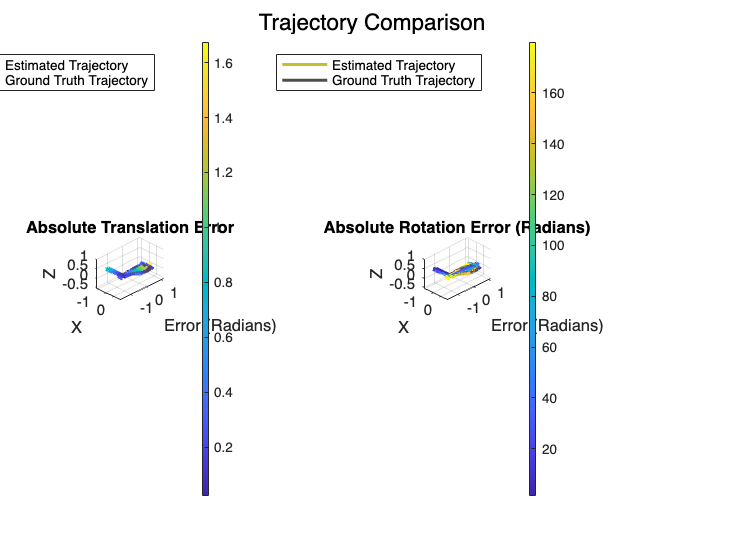

figure;
subplot(1, 2, 1)
plot(metrics, "absolute-translation");
title('Absolute Translation Error');
ylabel('Error (Radians)');
grid on;
view(45, 30);

subplot(1, 2, 2)
plot(metrics, "absolute-rotation");
title('Absolute Rotation Error (Radians)'); % Update title for clarity
ylabel('Error (Radians)');
grid on;
view(45, 30);
sgtitle('Trajectory Comparison');

disp('--- compareTrajectories executed and plotted successfully. ---');

--- compareTrajectories executed and plotted successfully. ---


## Evaluation Metrics

fprintf('Starting Evaluation Script...\n');

Starting Evaluation Script...



% ------------------ Extract Data ------------------ %
% Assumes 'out' and 'X_Est' are already loaded/generated
pos_GT_orig   = data.out.GT_position.signals.values;
rot_GT_quat_wxyz = data.out.GT_rotation.signals.values; % w,x,y,z format
timeVec  = data.out.GT_time.time;


if isrow(timeVec), timeVec = timeVec'; end
fprintf('Extracted GT Position, Rotation, and Time.\n');

Extracted GT Position, Rotation, and Time.




% --- Handle Potential Transpose Issues ---
if size(pos_GT_orig, 2) ~= 3 && size(pos_GT_orig, 1) == 3, pos_GT_orig = pos_GT_orig'; fprintf('Transposed original GT position data.\n'); end
if size(rot_GT_quat_wxyz, 2) ~= 4 && size(rot_GT_quat_wxyz, 1) == 4, rot_GT_quat_wxyz = rot_GT_quat_wxyz'; fprintf('Transposed original GT rotation data.\n'); end
% --- End Transpose Handling ---


% ------------------ Ensure Consistent Lengths ------------------ %
% --- MODIFIED EKF Output Check ---
% X_Est is now 3xN as generated by the class-based EKF.
if size(X_Est, 1) ~= 3 && size(X_Est, 2) == 3
    warning('X_Est seems to be Nx3, transposing to 3xN for consistency.');
    X_Est = X_Est';
elseif size(X_Est, 1) ~= 3
     error('X_Est should have 3 rows (x, y, yaw), but found %d rows.', size(X_Est, 1));
end
N_est = size(X_Est, 2); % Number of columns is N
% --- End Modified Check ---


N_gt_pos = size(pos_GT_orig, 1); N_gt_rot = size(rot_GT_quat_wxyz, 1);
N_time = length(timeVec);
N = min([N_gt_pos, N_gt_rot, N_time, N_est]);


if N < max([N_gt_pos, N_gt_rot, N_time, N_est])
    fprintf('--- Warning: Truncating data lengths from max(%d, %d, %d, %d) to shortest N = %d ---\n', N_gt_pos, N_gt_rot, N_time, N_est, N);
    pos_GT = pos_GT_orig(1:N, :); rot_GT_quat_wxyz = rot_GT_quat_wxyz(1:N, :);
    timeVec = timeVec(1:N); X_Est = X_Est(:, 1:N); % Use columns for EKF state
else
    fprintf('--- Data lengths consistent: N = %d ---\n', N);
    pos_GT = pos_GT_orig;
    % Ensure X_Est is also truncated if it was longer but N determined by GT/time
    if size(X_Est, 2) > N
        X_Est = X_Est(:, 1:N);
    end
end

--- Data lengths consistent: N = 6791 ---


if N == 0, error('Effective data length is zero after checking consistency.'); end


% ------------------ Convert Ground Truth Rotation to Yaw ------------------ %
fprintf('Converting Ground Truth rotation to Yaw (N=%d)...\n', N);

Converting Ground Truth rotation to Yaw (N=6791)...


yaw_GT = zeros(N, 1); valid_gt_quat = true(N, 1);
for i = 1:N
    qGT = quaternion(rot_GT_quat_wxyz(i,1), rot_GT_quat_wxyz(i,2), rot_GT_quat_wxyz(i,3), rot_GT_quat_wxyz(i,4));
    qGT = normalize(qGT); eulGT = eulerd(qGT, 'ZYX', 'frame'); yaw_GT(i) = deg2rad(eulGT(1));
end
yaw_GT = wrapToPi(yaw_GT);


% ------------------ Get Estimated Yaw ------------------ %
if size(X_Est, 1) < 3, error('X_Est does not contain Yaw data in the 3rd row.'); end
yaw_Est = wrapToPi(X_Est(3, :)'); % Get 3rd row, transpose to column, wrap
fprintf('Extracted Estimated Yaw.\n');

Extracted Estimated Yaw.




% ------------------ Convert Poses to rigidtform3d (Optional) --- %
% ... (code for rigidtform3d conversion remains the same) ...
fprintf('Converting poses to rigidtform3d arrays (N=%d)...\n', N);

Converting poses to rigidtform3d arrays (N=6791)...


gtTforms(N) = rigidtform3d; estTforms(N) = rigidtform3d;
valid_gt_pose = false(N,1); valid_est_pose = false(N,1); % Track valid poses
for i = 1:N
     % GT Pose
     if valid_gt_quat(i) && ~any(isnan(pos_GT(i,:)))
        try
            qGT = quaternion(rot_GT_quat_wxyz(i,1:4)); qGT = normalize(qGT); RGT = rotmat(qGT, 'frame'); tGT = pos_GT(i,1:min(3,end));
            if length(tGT) == 2, tGT = [tGT, 0]; end; gtTforms(i) = rigidtform3d(RGT, tGT(:)'); valid_gt_pose(i) = true;
        catch ME_gt_tform, warning('Error creating GT rigidtform3d at index %d: %s', i, ME_gt_tform.message); gtTforms(i) = rigidtform3d(); end
     else, gtTforms(i) = rigidtform3d(); end
     % Est Pose
    if ~any(isnan(X_Est(1:2, i))) && ~isnan(yaw_Est(i))
        try
            tEst = [X_Est(1, i), X_Est(2, i), 0]; yaw_est_i = yaw_Est(i);
            REst = [cos(yaw_est_i), -sin(yaw_est_i), 0; sin(yaw_est_i), cos(yaw_est_i), 0; 0, 0, 1];
            estTforms(i) = rigidtform3d(REst, tEst); valid_est_pose(i) = true;
        catch ME_est_tform, warning('Error creating Est rigidtform3d at index %d: %s', i, ME_est_tform.message); estTforms(i) = rigidtform3d(); end
    else, estTforms(i) = rigidtform3d(); end
end
fprintf('Pose conversions complete.\n');

Pose conversions complete.


fprintf('\n--- Trajectory Comparison Results ---\n');


--- Trajectory Comparison Results ---


%metrics = compareTrajectories(estTforms(validIdx), gtTforms(validIdx), 'AlignmentType', 'none');
metrics = compareTrajectories(estTforms, gtTforms, 'AlignmentType', 'none');
fprintf('compareTrajectories executed (Specific metrics below are calculated manually).\n');

compareTrajectories executed (Specific metrics below are calculated manually).



% --- Calculate and Print Manual Position and Yaw Absolute RMSE --- %
% Position RMSE (Manual Calculation)
valid_pos_idx = ~isnan(X_Est(1, :))' & ~isnan(X_Est(2, :))' & ~isnan(pos_GT(:, 1)) & ~isnan(pos_GT(:, 2)); % Check EKF output columns
if sum(valid_pos_idx) > 0 && size(X_Est, 1) >= 2 && size(pos_GT, 2) >= 2 % Check EKF rows
    pos_err_x = X_Est(1, valid_pos_idx)' - pos_GT(valid_pos_idx, 1); % Transpose EKF part
    pos_err_y = X_Est(2, valid_pos_idx)' - pos_GT(valid_pos_idx, 2); % Transpose EKF part
    squared_pos_err = pos_err_x.^2 + pos_err_y.^2;
    rmse_position = sqrt(mean(squared_pos_err));
    fprintf('Position Absolute RMSE (Manual) (m):     %.4f\n', rmse_position);
else
    fprintf('Position Absolute RMSE (Manual) (m):     Cannot calculate.\n');
    rmse_position = NaN;
end

Position Absolute RMSE (Manual) (m):     0.2969




% Yaw RMSE (Manual Calculation)
valid_yaw_idx = ~isnan(yaw_Est) & ~isnan(yaw_GT);
if sum(valid_yaw_idx) > 0
    yaw_error = wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx));
    squared_yaw_err = yaw_error.^2;
    rmse_yaw_rad = sqrt(mean(squared_yaw_err));
    rmse_yaw_deg = rad2deg(rmse_yaw_rad);
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    %.4f\n', rmse_yaw_deg);
else
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    Cannot calculate.\n');
    rmse_yaw_deg = NaN;
end

Yaw Absolute RMSE (Manual) (degrees):    4.3142


fprintf('--- End Trajectory Comparison Results ---\n\n');

--- End Trajectory Comparison Results ---





% ------------------ Plot Position Comparison (Subplots) ------------------ %
% ... (Position plot code remains the same) ...
fprintf('Plotting Position: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Position: Ground Truth (Left) vs Estimate (Right)...


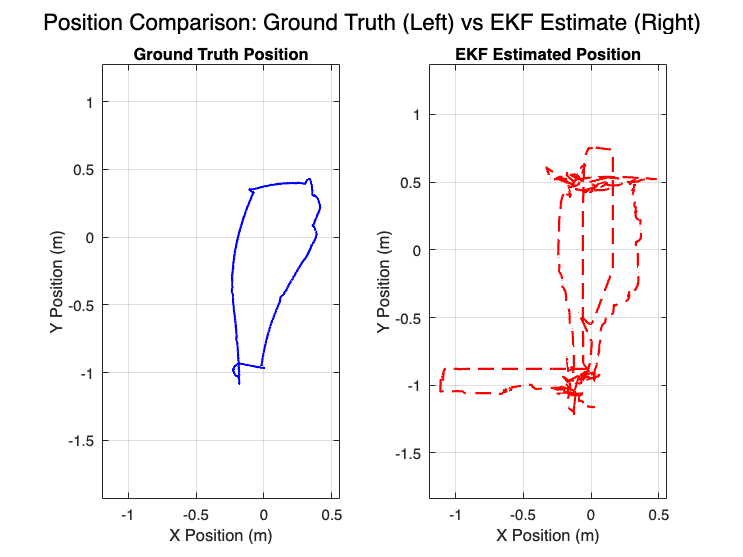

figure('Name', 'Position Comparison');
all_x = [pos_GT(:,1); X_Est(1,:)']; all_y = [pos_GT(:,2); X_Est(2,:)']; % Transpose EKF
x_lim = [min(all_x) max(all_x)]; y_lim = [min(all_y) max(all_y)];
x_range = diff(x_lim); y_range = diff(y_lim); margin = 0.05;
x_lim = x_lim + [-x_range*margin, x_range*margin]; y_lim = y_lim + [-y_range*margin, y_range*margin];
if x_range == 0, x_lim = x_lim + [-0.1, 0.1]; end; if y_range == 0, y_lim = y_lim + [-0.1, 0.1]; end
subplot(1, 2, 1); plot(pos_GT(:,1), pos_GT(:,2), 'b-', 'LineWidth', 1.5); title('Ground Truth Position'); xlabel('X Position (m)'); ylabel('Y Position (m)'); xlim(x_lim); ylim(y_lim); axis equal; grid on;
subplot(1, 2, 2); plot(X_Est(1,:), X_Est(2,:), 'r--', 'LineWidth', 1.5); title('EKF Estimated Position'); xlabel('X Position (m)'); ylabel('Y Position (m)'); xlim(x_lim); ylim(y_lim); axis equal; grid on;
try, sgtitle('Position Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end



% ------------------ Plot Yaw Comparison (Subplots) ------------------ %
% ... (Individual Yaw plot code remains the same) ...
fprintf('Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...


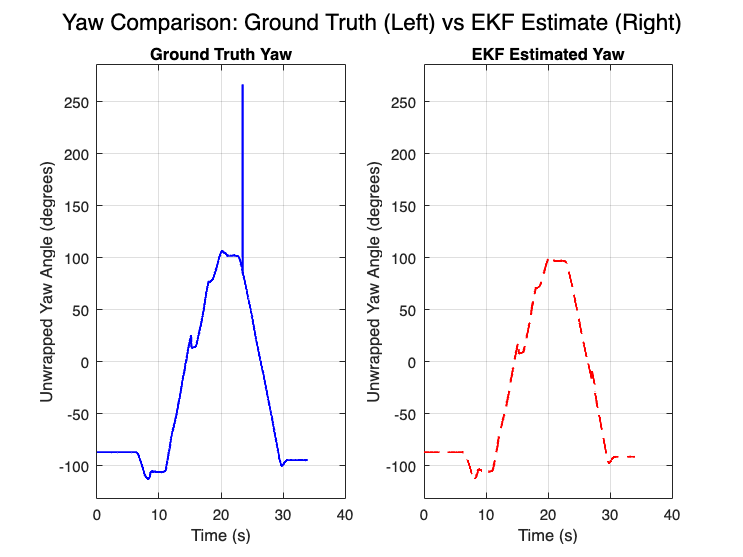

figure('Name', 'Yaw Comparison');
if sum(valid_yaw_idx) > 0
    unwrapped_yaw_gt_deg = rad2deg(unwrap(yaw_GT(valid_yaw_idx))); unwrapped_yaw_est_deg = rad2deg(unwrap(yaw_Est(valid_yaw_idx)));
    all_yaw_deg = [unwrapped_yaw_gt_deg; unwrapped_yaw_est_deg]; y_lim_yaw = [min(all_yaw_deg) max(all_yaw_deg)];
    y_range_yaw = diff(y_lim_yaw); y_lim_yaw = y_lim_yaw + [-y_range_yaw*margin, y_range_yaw*margin];
    if y_range_yaw == 0, y_lim_yaw = y_lim_yaw + [-10, 10]; end
    subplot(1, 2, 1); plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5); title('Ground Truth Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;
    subplot(1, 2, 2); plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5); title('EKF Estimated Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;
    try, sgtitle('Yaw Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end
else, subplot(1,1,1); title('Yaw Comparison (No valid data to plot)'); end



% ------------------ Plot Yaw Error ------------------ %
% ... (Yaw Error plot code remains the same) ...
fprintf('Plotting Yaw Estimation Error...\n');

Plotting Yaw Estimation Error...


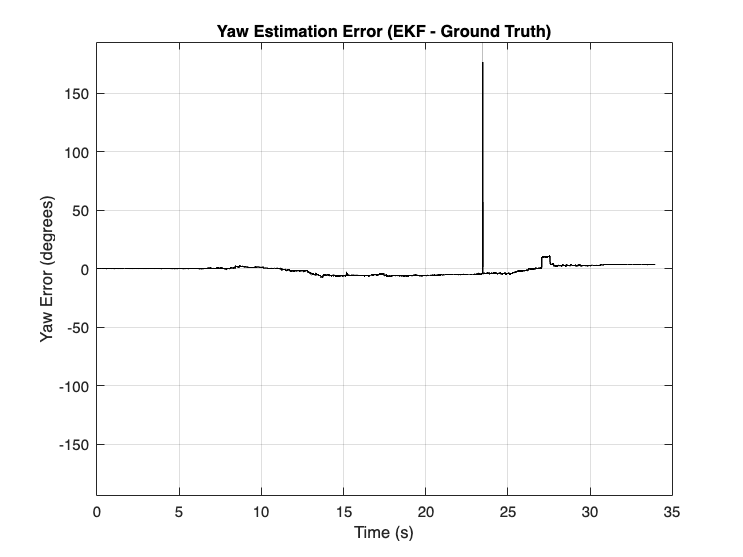

figure('Name', 'Yaw Estimation Error');
if sum(valid_yaw_idx) > 0
    yaw_error_deg = rad2deg(wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx)));
    plot(timeVec(valid_yaw_idx), yaw_error_deg, 'k-', 'LineWidth', 1); xlabel('Time (s)'); ylabel('Yaw Error (degrees)'); title('Yaw Estimation Error (EKF - Ground Truth)'); grid on;
    max_err = max(abs(yaw_error_deg)); if ~isnan(max_err) && max_err > 0, ylim([-max(1, max_err*1.1), max(1, max_err*1.1)]); end
else, title('Yaw Estimation Error (No valid data to plot)'); end



% --- !!! NEW PLOT: OVERLAY GT vs ESTIMATED YAW !!! ---
fprintf('Plotting Yaw Overlay: Ground Truth vs Estimate...\n');

Plotting Yaw Overlay: Ground Truth vs Estimate...


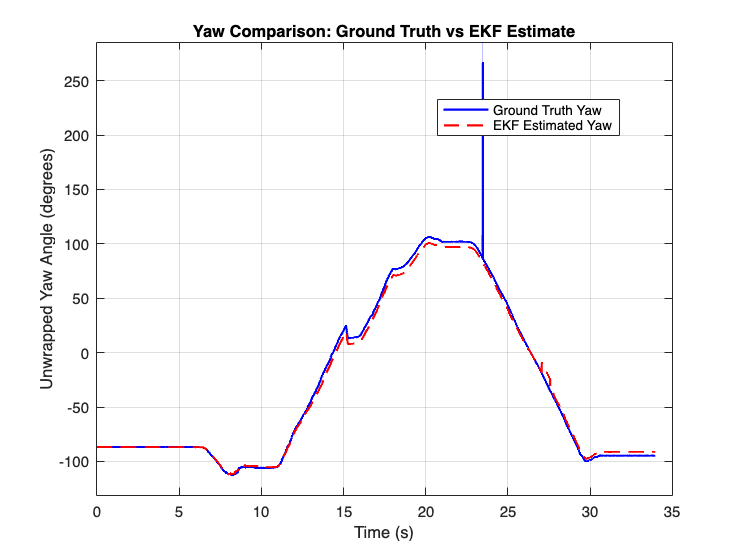

figure('Name', 'Yaw Comparison: GT vs Estimate'); % Create a new figure
if sum(valid_yaw_idx) > 0
    % Use the unwrapped angles already calculated
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5);
    hold on; % Keep the plot for the next line
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5);
    hold off; % Release the plot

    % Add labels and legend
    xlabel('Time (s)');
    ylabel('Unwrapped Yaw Angle (degrees)');
    title('Yaw Comparison: Ground Truth vs EKF Estimate');
    legend('Ground Truth Yaw', 'EKF Estimated Yaw', 'Location', 'best');
    grid on;
    % Use the same y-limits as the individual yaw plots for consistency
    ylim(y_lim_yaw);
else
    title('Yaw Comparison: GT vs Estimate (No valid data to plot)');
end

% --- !!! END NEW PLOT !!! ---

fprintf('--- End of Evaluation Script ---\n');

--- End of Evaluation Script ---


## EKF Functions

Prediction

function predict(obj, gyro_z_raw, accel_fwd_raw, dt)
    % Predicts state using gyro for yaw rate and accelerometer for velocity estimation.
    % Adapted from the logic in myEKF.

    if dt <= 0
        warning('dt is non-positive (%.4f) in predict step. Skipping prediction.', dt);
        return;
    end

    % --- Previous State ---
    x_prev = obj.x;
    P_prev = obj.P;
    yaw_prev = x_prev(3); % Already normalized from previous step or init

    % --- Process Inputs ---
    % Correct Gyro Reading
    omega_z_corrected = gyro_z_raw - obj.gyro_bias_z;

    % Correct Accelerometer Reading and Update Velocity Estimate
    accel_fwd_corrected = accel_fwd_raw - obj.accel_bias_fwd;
    obj.current_v_est = obj.current_v_est + accel_fwd_corrected * dt; % Integrate acceleration
    % Optional: Add damping or limits to velocity estimate if needed
    %e.g., obj.current_v_est = obj.current_v_est * 0.99;

    % --- State Transition Model f(x, u) ---
    % Predict next state based on previous state, corrected inputs, and estimated velocity
    x_pred = zeros(3,1);
    x_pred(1) = x_prev(1) + obj.current_v_est * cos(yaw_prev) * dt;
    x_pred(2) = x_prev(2) + obj.current_v_est * sin(yaw_prev) * dt;
    x_pred(3) = yaw_prev + omega_z_corrected * dt;
    x_pred(3) = normalizeAngle(x_pred(3)); % Normalize predicted angle

    % --- State Transition Jacobian F ---
    % Jacobian of f w.r.t. x = [x, y, yaw]
    F = [ 1  0  -obj.current_v_est * sin(yaw_prev) * dt;
        0  1   obj.current_v_est * cos(yaw_prev) * dt;
        0  0   1 ];

     % --- Process Noise Covariance Q_k ---
     % Calculate the process noise covariance for this time step dt
     % This matches the structure in myEKF where Q depends on dt and noise parameters
     % Term related to uncertainty propagation due to acceleration noise
     Q_pos_from_accel = (0.5 * obj.w_accel * dt^2)^2;

     % Combine position noise (from base process noise + accel uncertainty)
     % and yaw rate noise
     Q_k = diag([ (obj.w_pos * dt)^2 + Q_pos_from_accel, ...
                  (obj.w_pos * dt)^2 + Q_pos_from_accel, ...
                  (obj.w_yaw_rate * dt)^2 ]);

     % --- Predict Covariance ---
     obj.P = F * P_prev * F' + Q_k;

     % Ensure P remains symmetric (optional but good practice)
     obj.P = 0.5 * (obj.P + obj.P');

     % --- Update State ---
     obj.x = x_pred;

     end % End predict method

Update

function update(obj, z)
    z = double(z(:));
    h_x = compute_measurement_model_h(obj, obj.x);
    H = compute_numerical_jacobian_H(obj, obj.x); % Calculate full Jacobian
    
    % Temporarily disable ToF updates for the Yaw state (state index 3)
    % Set the 3rd column of H (dh/dyaw) to zero before calculating gain
    disable_tof_yaw_update = true; % Set to false to re-enable
    if disable_tof_yaw_update
        H_modified = H;
        H_modified(:, 3) = 0; % Zero out sensitivity to yaw
        fprintf('DEBUG: ToF Yaw update DISABLED.\n'); % Add message
    else
        H_modified = H; % Use original Jacobian
        fprintf('DEBUG: ToF Yaw update ENABLED.\n'); % Add message
    end
    % --- <<< END OF DEBUGGING MODIFICATION >>> ---
    
    if all(H_modified == 0, 'all') % Use modified H here
        warning('Measurement Jacobian H (potentially modified) is all zeros. Skipping update.');
        return;
    end

    % Use H_modified for Kalman Gain calculation
    S = H_modified * obj.P * H_modified' + obj.R; % Use modified H

    if cond(S) > 1/eps
        warning('Innovation covariance matrix S is singular or ill-conditioned (cond=%.2e). Skipping update.', cond(S));
        return;
    end
    
    K = obj.P * H_modified' / S; % Use modified H
    y = z - h_x;
    obj.x = obj.x + K * y; % Update state (Yaw won't be affected if H_modified(:,3) was 0)
    obj.x(3) = normalizeAngle(obj.x(3));

    I = eye(size(obj.P,1));
    obj.P = (I - K * H_modified) * obj.P * (I - K * H_modified)' + K * obj.R * K';

    obj.P = 0.5 * (obj.P + obj.P');
    [V, D] = eig(obj.P);
    D(D < 0) = eps;
    obj.P = V * D * V';
end

### Helper Functions

function h = compute_measurement_model_h(obj, state)
    % Computes the expected measurement vector h(x) for all sensors.
    h = zeros(3, 1);
    for i = 1:3
        h(i) = calculate_expected_tof_single(obj, state, i);
    end
end

function dist = calculate_expected_tof_single(obj, state, sensor_index)
    % Calculates the expected distance for a single ToF sensor using ray casting.
    x_r = state(1);
    y_r = state(2);
    yaw_r = state(3); % Already normalized in predict/update

    rel_pos_sensor = obj.tof_rel_pos(:, sensor_index); % [x_rel; y_rel]
    rel_angle_sensor = obj.tof_rel_angle(sensor_index);

    % Calculate sensor's global position
    c_yaw = cos(yaw_r);
    s_yaw = sin(yaw_r);
    rot_matrix = [c_yaw, -s_yaw; s_yaw, c_yaw];
    sensor_offset_world = rot_matrix * rel_pos_sensor;
    sx_global = x_r + sensor_offset_world(1);
    sy_global = y_r + sensor_offset_world(2);

    % Calculate sensor's global orientation (angle)
    s_yaw_global = normalizeAngle(yaw_r + rel_angle_sensor);
    c_s_yaw = cos(s_yaw_global);
    s_s_yaw = sin(s_yaw_global);

    % Calculate distances to walls along the sensor's ray
    distances = [];
    limits = obj.arena_dim;

    % Right wall (x = x_max)
    if abs(c_s_yaw) > obj.epsilon % Check if ray is not parallel to wall
        d = (limits.x_max - sx_global) / c_s_yaw;
        py = sy_global + d * s_s_yaw; % Intersection y-coord
        if d > obj.epsilon && py >= limits.y_min && py <= limits.y_max
            distances = [distances, d];
        end
    end

    % Left wall (x = x_min)
    if abs(c_s_yaw) > obj.epsilon
        d = (limits.x_min - sx_global) / c_s_yaw;
        py = sy_global + d * s_s_yaw;
        if d > obj.epsilon && py >= limits.y_min && py <= limits.y_max
            distances = [distances, d];
        end
    end

    % Top wall (y = y_max)
    if abs(s_s_yaw) > obj.epsilon % Check if ray is not parallel to wall
        d = (limits.y_max - sy_global) / s_s_yaw;
        px = sx_global + d * c_s_yaw; % Intersection x-coord
        if d > obj.epsilon && px >= limits.x_min && px <= limits.x_max
            distances = [distances, d];
        end
    end

    % Bottom wall (y = y_min)
    if abs(s_s_yaw) > obj.epsilon
        d = (limits.y_min - sy_global) / s_s_yaw;
        px = sx_global + d * c_s_yaw;
        if d > obj.epsilon && px >= limits.x_min && px <= limits.x_max
            distances = [distances, d];
        end
    end

    % Return the minimum valid distance
    if isempty(distances)
        warning('EKF:NoWallHit', 'Sensor %d ray did not hit any wall segments. State: [%.2f, %.2f, %.2f rad]', sensor_index, x_r, y_r, yaw_r);
        dist = 10.0; % Return a large distance
    else
        dist = min(distances);
    end
end

function H = compute_numerical_jacobian_H(obj, state, delta)
    % Computes the measurement Jacobian H numerically using central differences.
    if nargin < 3
        delta = 1e-7;
    end
    H = zeros(3, 3);
    for j = 1:3
        x_plus = state; x_minus = state;
        x_plus(j) = x_plus(j) + delta;
        x_minus(j) = x_minus(j) - delta;
        if j == 3 % Normalize yaw if perturbed
            x_plus(3) = normalizeAngle(x_plus(3));
            x_minus(3) = normalizeAngle(x_minus(3));
        end
        h_plus = compute_measurement_model_h(obj, x_plus);
        h_minus = compute_measurement_model_h(obj, x_minus);
        derivative = (h_plus - h_minus) / (2 * delta);
        H(:, j) = derivative;
    end
end

function normalized = normalizeAngle(angle)
    % Normalize an angle to the range [-pi, pi].
    normalized = mod(angle + pi, 2*pi) - pi;
end
